# Sistemas de Control II - FCEFyN (UNC)

## Caso de estudio 2 - Motor (Actividad 1.5)

clear all; close all; clc;

data= readtable('../Resources/Curvas_Medidas_Motor_2025_v.xls');
data;
% Convert table to array. Apply transpose.
dataT= table2array(data);

% Obtain time(t).
t  = dataT(:,1);
wr = dataT(:,2);
ia = dataT(:,3);
v  = dataT(:,4);

Plot measurements

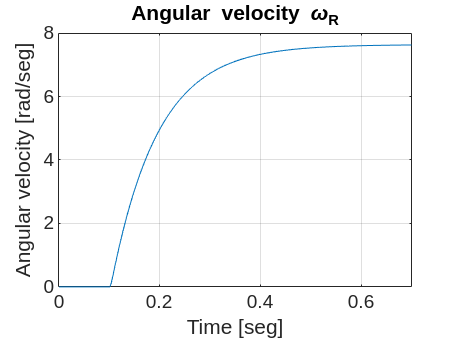

figure(1); plot(t, wr); title('Angular velocity \omega_{R}'); 
ylabel('Angular velocity [rad/seg]'); xlabel('Time [seg]');
grid on; xlim([0, 0.7]);

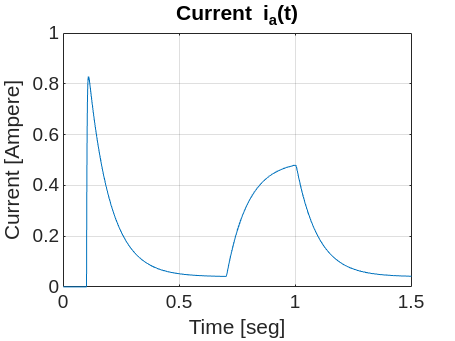

figure(2); plot(t, ia); title('Current i_{a}(t)'); 
ylabel('Current [Ampere]'); xlabel('Time [seg]');
grid on;

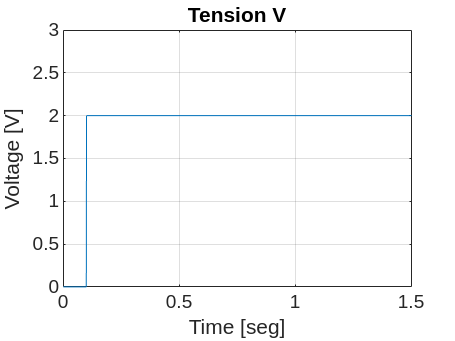

figure(3); plot(t, v); title('Tension V'); 
ylabel('Voltage [V]'); xlabel('Time [seg]');
grid on; ylim([0, 3])

Apply Chen Method to $$ Angular \, velocity \, (\omega_{R}) $$

K= max(wr)/1;

i  = 155;
h  = 60;

t1 = t(i);
y1 = wr(i)

y1 = 3.2604

t2 = t(i+h);
y2 = wr(i+h)

y2 = 5.3498

t3 = t(i+2*h);
y3 = wr(i+2*h)

y3 = 6.4416


deltaTime= t2-t1

deltaTime = 0.0600

delayTime= 0.102;

TF= minreal(chenMethod(y1, y2, y3, K, deltaTime, delayTime));
disp('Transfer Function: ')

Transfer Function: 


TF


TF =
 
                          5969
  exp(-0.102*s) * ---------------------
                  s^2 + 82.73 s + 782.8
 
Continuous-time transfer function.
Model Properties



disp('Poles and zeros: ')

Poles and zeros: 


pole(TF)

ans =   -71.8304
  -10.8977


zero(TF)


ans =

  0×1 empty double column vector



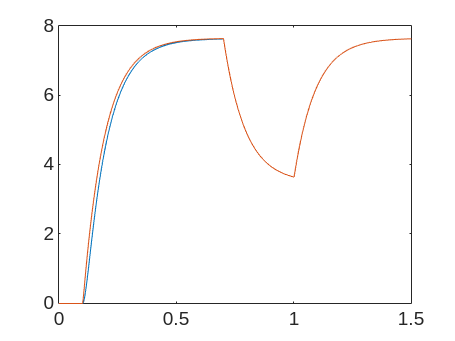


figure(4);
[ys, ts]= step(TF, 0.7);
figure(5);
plot(ts, ys, t, wr);